% === RN黑洞光线追踪主程序 (郑氏架构版) ===
clear; clc;

% 1. 参数设置
npix = 700;           % 想要高清就改大
M = 1;
Q = -1;             % Q=0 是史瓦西，Q=0.95 是 RN
fov = pi/5;
% 修改观测位置
% 建议把角度改成 80度 (80*pi/180) 或者 75度
% 距离 r_obs = 30 比较合适
pos = [0, 40, 80*pi/180, 0];
fprintf('初始化测地线方程 (符号计算可能需要几秒钟)...\n');

初始化测地线方程 (符号计算可能需要几秒钟)...


odefun = geodesic_RN(M, Q); % 生成方程句柄

fprintf('开始光线追踪 (RN Black Hole, Q=%g)...\n', Q);

开始光线追踪 (RN Black Hole, Q=-1)...


Result = zeros(npix, npix);

% 2. 并行计算 (如果没有并行工具箱，把 parfor 改成 for)
% parfor_progress(npix); % 如果你有那个进度条脚本就取消注释
tic;
for j = 1:npix
    if mod(j, 10) == 0, fprintf('Processing row %d/%d\n', j, npix); end
    
    for i = 1:npix
        % 调用单光线追踪
        Result(i, j) = TraceSingleRay_RN(pos', fov, npix, i, j, M, Q, odefun);
    end
    % parfor_progress;
end

Processing row 10/700
Processing row 20/700
Processing row 30/700
Processing row 40/700
Processing row 50/700
Processing row 60/700
Processing row 70/700
Processing row 80/700
Processing row 90/700
Processing row 100/700
Processing row 110/700
Processing row 120/700
Processing row 130/700
Processing row 140/700
Processing row 150/700
Processing row 160/700
Processing row 170/700
Processing row 180/700
Processing row 190/700
Processing row 200/700
Processing row 210/700
Processing row 220/700
Processing row 230/700
Processing row 240/700
Processing row 250/700
Processing row 260/700
Processing row 270/700
Processing row 280/700
Processing row 290/700
Processing row 300/700
Processing row 310/700
Processing row 320/700
Processing row 330/700
Processing row 340/700
Processing row 350/700
Processing row 360/700
Processing row 370/700
Processing row 380/700
Processing row 390/700
Processing row 400/700
Processing row 410/700
Processing row 420/700
Processing row 430/700
Processing row 440/7

% parfor_progress(0);
toc;

历时 415.420880 秒。


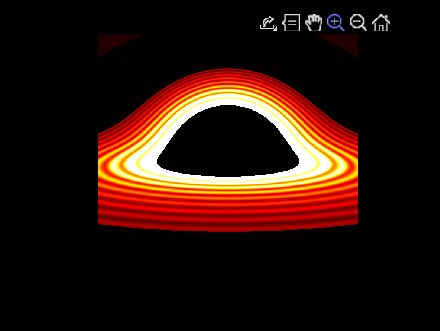


% 3. 绘图与可视化
Result = rot90(Result); % 郑力恒的习惯，因为矩阵坐标和图像坐标的关系
figure(1);
imagesc(Result);
colormap('hot');
axis off equal;
set(gcf, 'Color', 'k'); % 背景设为黑
title(['RN Black Hole Shadow (Q=' num2str(Q) ')']);

function g = gdown_RN(r, th, M, Q)
% RN黑洞的下标形式度规
% 修正版：修复了第4行少写一个0导致的维度错误 (＞﹏＜)
    format long
    
    % 几何因子 f(r)
    f = 1 - 2*M/r + Q^2/r^2;
    
    % 对角矩阵 (4x4)
    g = [-f,    0,    0,    0;
          0,  1/f,    0,    0;
          0,    0,  r^2,    0;
          0,    0,    0,  r^2*sin(th)^2]; % <--- 之前这里少了一个 0 ！
end
function zamo = localtetrad_RN(metric)
% RN黑洞的局域正交标架
% 修正版：严格模仿郑力恒风格，修正了 e1 和 e3 的方向
% 之前的代码会导致光线向外发射，拍不到黑洞！(＞﹏＜)

    g11 = metric(1,1);
    g22 = metric(2,2);
    g33 = metric(3,3);
    g44 = metric(4,4);
    
    % e0: 时间方向
    e0 = [1/sqrt(-g11), 0, 0, 0];
    
    % e1: 径向 (注意这里要有负号！表示指向黑洞内部)
    e1 = [0, -1/sqrt(g22), 0, 0]; 
    
    % e2: 极角方向
    e2 = [0, 0, 1/sqrt(g33), 0];
    
    % e3: 方位角方向 (郑力恒代码里这里也取了负号，可能是为了配合像素坐标系)
    e3 = [0, 0, 0, -1/sqrt(g44)];
    
    zamo = [e0; e1; e2; e3];
end
function momentumup = GetRayMomentum_RN(metric, fov, npix, i, j)
% 计算光线在局域标架下的动量，并投影到全局坐标
% 严格模仿 GetRayMomentum.m

    format long
    
    % 屏幕坐标映射
    xs = 2*tan(fov/2)/npix * (i - 1/2*(npix+1));
    ys = 2*tan(fov/2)/npix * (j - 1/2*(npix+1));
    
    % 转换角度 (注意：这里模仿原代码的逻辑)
    thx = atan(sqrt(xs^2 + ys^2));
    
    % 简单的 atanp 实现：
   % 原来的写法（会导致图像旋转90度）：
    % psix = atan2(-ys, -xs); 
    
    % === 修正后的写法 (Standard Orientation) ===
    % 让屏幕 Y 轴指向上方 (北极, -theta方向)
    % 让屏幕 X 轴指向右方 (东, +phi方向)
    % 对应关系: cos(psi) ~ -y, sin(psi) ~ x
    psix = atan2(xs, -ys);
    if psix < 0
        psix = psix + 2*pi;
    end
    
    % 局域光子动量 (朝向黑洞, t分量为-1)
    vel = [cos(thx), sin(thx)*cos(psix), sin(thx)*sin(psix)];
    
    % 获取标架
    zamo = localtetrad_RN(metric);
    
    kappa = 1;
    % 投影到全局坐标 (上指标)
    momentumup = ([-kappa, kappa*vel] * zamo)'; 
end
function odefun = geodesic_RN(M, Q)
% 使用符号工具箱生成测地线方程句柄
% 修正版：解决了 'Vars' 参数无效的错误
    
    % 1. 定义符号变量
    % 注意：我们增加一个 'tau' 代表仿射参数(ode45的时间t)
    syms t r th ph pt pr pth pph tau real
    
    % 2. 构建符号度规
    f_sym = 1 - 2*M/r + Q^2/r^2;
    g_down_sym = diag([-f_sym, 1/f_sym, r^2, r^2*sin(th)^2]);
    g_up_sym = inv(g_down_sym); % 上标度规求逆
    
    % 3. 哈密顿量 H = 0.5 * g^uv * p_u * p_v
    p = [pt; pr; pth; pph];
    Hsyms = 0.5 * p' * g_up_sym * p;
    
    % 4. 哈密顿方程 (8个方程)
    % dx/dlambda = dH/dp
    % dp/dlambda = -dH/dx
    vars = [t; r; th; ph; pt; pr; pth; pph];
    
    eqs = [diff(Hsyms, pt);
           diff(Hsyms, pr);
           diff(Hsyms, pth);
           diff(Hsyms, pph);
           -diff(Hsyms, t);
           -diff(Hsyms, r);
           -diff(Hsyms, th);
           -diff(Hsyms, ph)];
           
    % 5. 转化为函数句柄
    % 关键修改：用 {tau, vars} 代替 {0, vars}
    % 这样生成的函数就是 @(tau, vars) ... 符合 ode45 的要求
    
    odefun_sym = matlabFunction(eqs, 'Vars', {tau, vars}); 
    
    odefun = odefun_sym;
end
function II = TraceSingleRay_RN(pos, fov, npix, i, j, M, Q, odefun)
% 单条光线追踪
% 模仿 TraceSingleRay 系列函数

    format long
    
    % 1. 准备初值
    metric = gdown_RN(pos(2), pos(3), M, Q);
    momentumup = GetRayMomentum_RN(metric, fov, npix, i, j);
    momentumdown = metric * momentumup; % 降指标得到正则动量 p_mu
    
    initialconditions = [pos; momentumdown];
    
    % 2. 积分设置
    lambdaf = 500; % 积分长度
    
    % 视界半径估算 (用于停止积分)
    if M > abs(Q)
        r_horizon = M + sqrt(M^2 - Q^2);
    else
        r_horizon = 0;
    end
    
    % 事件函数：检测落入视界或逃逸
    opts = odeset('Events', @(t,u) myevent(t,u,r_horizon), 'RelTol', 1e-5, 'AbsTol', 1e-6);
    
    % 3. 执行 ODE
    % 注意：geodesic_RN 返回的句柄已经包含了 M 和 Q
    [~, ~, ~, ue, ie] = ode45(odefun, [0 lambdaf], initialconditions, opts);
    
    % 4. 上色逻辑 (模仿 InfiniteDisk.m)
    II = 0; % 默认黑色
    
    if ~isempty(ie)
        last_event = ie(end);
        
        % 事件3: 撞击赤道面 (吸积盘)
        if last_event == 3
            r_hit = ue(end, 2);
            % 简单的吸积盘纹理
             II = Diskvalue(r_hit);
             
        % 事件2: 逃逸 (天空)
        elseif last_event == 2
            II = 0.05; % 微弱的背景光
        end
        % 事件1: 落入视界 (保持黑色 II=0)
    end
    
    % --- 内部函数：事件 ---
    function [value, isterminal, direction] = myevent(~, u, r_h)
        % u(2) 是 r, u(3) 是 theta
        value = [u(2) - 1.01*r_h;      % 事件1: 落入视界
                 u(2) - 100;           % 事件2: 逃逸
                 u(3) - pi/2];         % 事件3: 撞击赤道面
        isterminal = [1; 1; 1];        % 遇到任何一个都停止 (无限薄盘逻辑)
        direction = [0; 0; 0];
    end

    % --- 内部函数：盘面纹理 ---
   function val = Diskvalue(r)
        % 环状吸积盘范围: 6M < r < 20M
        if r > 6 && r < 20
             % 基础亮度
             val = 1; 
             
             % === 增加同心圆纹理 ===
             % 用 sin 函数生成平滑的环，而不是原来的 floor 方块
             % 这样你能看清盘面的扭曲
             val = val * (0.5 + 0.5 * sin(r * 2)^2);
             
             % 距离衰减 (内圈亮，外圈暗)
             val = val * (100 / r^2);
             
             % 限制最大亮度
             val = min(val, 1);
        else
             val = 0;
        end
    end
end
